%Limpieza de pantalla
clear all
close all
clc

Declaramamos nuestras variables simbolicas que van a ser nuestra articulacion y su angulo $\;\theta_1$, las longitudes l1 y l2, y el tiempo 

%Declaración de variables simbólicas
syms th1(t) l1(t) l2(t) t a1

Creamos el vector de configuracion en el que indicamos que la primera articulacion es rotacional y las 2 ultimas son prismaticas

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

Creamos el vector de coordenadas articulares

Q= [th1, l1, l1];
%disp('Coordenadas generalizadas');
%pretty (Q);


Creamos el vector de velocidades generalizadas

Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);

Guardamos el numero de articulaciones que tiene nuestro robot a traves del vector de configuraciones creado previamente

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


## **Articulación 1 **

Creamos nuestro vector de posicion el cual esta solo esta afectado el cual va a variar tanto en X y Y porque va a girar entre esos ejes.

Tambien se crea nuestra matriz de rotacion respecto al  Z ya que es sobre el cual esta girando

%Posición de la articulación 1 respecto a 0
P(:,:,1)= [a1*cos(th1); a1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

## **Articulación 2 **

En nuestro vector de posicion se agraga la longitud 1 ya que como es prismatica es la unica que implica.

En cuanto a la matriz de rotación, se considera el mismo sistema de referencia que el de la imagen, por lo cual se hace una rotacion de -90° sobre el eje X, este valor es negativo ya que Z va Y, Por lo tanto al sustirtuir el angulo en la matriz de rotacion obtenemos como resultado la siguiente matriz

%% Articulación 2 
%Posición de la articulación 1 respecto a 0
P(:,:,2)= [0; l1; 0];
%Matriz de rotación de la junta 1 respecto a 0.... -90º
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];


## **Articulación 3 **

Se crea nuestro vector de posicion donde unicamente interviene la longitud de nuestra tercera articulacion.

Por ultimo, para nuestra ultima matriz de rotacion solo usamos la matriz identidad.

%% Articulación 3 
%Posición de la articulación 2 respecto a 1
P(:,:,3)= [0; 0; l2];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];
%% 
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

Como siguiente paso Inicializamos nuestras matrices de transformacion homogenas tanto locales como globales, las posiciones ya las rotaciones desde el marco de referencia inercial

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
PO(:,:,GDL)= P(:,:,GDL); 
RO(:,:,GDL)= R(:,:,GDL); 


Continuamos calculando nuestra matriz de transfomacion global


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, a1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, a1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)), a1 cos(th1(t)) - sin(th1(t)) l1(t) \
|                                                                   |
| sin(th1(t)),  0,  cos(th1(t)), a1 sin(th1(t)) + cos(th1(t)) l1(t) |
|                                                                   |
|      0,      -1,       0,                       0                 |
|                                                                   |
\      0,       0,       0,                       1                 /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)), a1 cos(th1(t)) - sin(th1(t)) l1(t) - sin(th1(t)) l2(t) \
|                                                                                       |
| sin(th1(t)),  0,  cos(th1(t)), a1 sin(th1(t)) + cos(th1(t)) l1(t) + cos(th1(t)) l2(t) |
|                                                                                       |
|      0,      -1,       0,                                 0                           |
|                                                                                       |
\      0,       0,       0,                                 1                           /



 %%

Se calcula el jacobiano lineal de manera diferencial esto usando las derivadas parciales. 

%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l1);
Jv13= functionalDerivative(PO(1,1,GDL), l2);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l1);
Jv23= functionalDerivative(PO(2,1,GDL), l2);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l1);
Jv33= functionalDerivative(PO(3,1,GDL), l2);

Construimos nuesta matriz del Jacobiano lineal a traves de las jacobianos lineales que se obtivieron anteriormente. 

jv_d=simplify([Jv11 Jv12 Jv13;
               Jv21 Jv22 Jv23;
               Jv31 Jv32 Jv33]);
%pretty(jv_d);



Calculamos el jacobiano lineal y angular de forma analítica

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

 %%
for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


## **Velocidad lineal obtenida mediante el Jacobiano lineal**

                                                    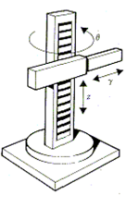

Al usar el mismo sistema de referencia, podemos notar que:

**En X**, debido a la rotacion de la primera articulacion va haber un punto en el que quede sobre el mismo eje, por tanto las demas articulaciones van a moverse tambien sobre X y va a haber una velociadad lineal 

**En Y, **como ya se muestra en la imagen, en este eje implican las tres articulaciones, debido a que la primera llego a un punto en el cual la segunda y tercera articualcion se muven sobre Y. 

Por ultimo, en el **eje Z **solo se desplaza la segunda articulacion (l1), la cual aunque haya una rotacion por parte de la primera articulacion, esta solo se va a mover en todo momento sobre Z

V=simplify (Jv_a*Qp');
pretty(V);

/ - #2 (a1 sin(th1(t)) + cos(th1(t)) l1(t) + cos(th1(t)) l2(t)) - #1 sin(th1(t)) \
|                                                                                |
|  #1 cos(th1(t)) - #2 (sin(th1(t)) l1(t) - a1 cos(th1(t)) + sin(th1(t)) l2(t))  |
|                                                                                |
\                                       #1                                       /

where

         ________
          d
   #1 == -- l1(t)
         dt

         _________
          d
   #2 == -- th1(t)
         dt




## **Velocidad angular obtenida mediante el Jacobiano angular**

Como resutado podemos ver que solo hay velocidad angular en el eje z, lo cual es logico ya que es el unico eje sobre el cual hay una rotacion y esta pertenece a la de la primera articulacion. 

W=simplify (Jw_a*Qp');
    pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /

